# 布特沃斯滤波器测试

`     staN      ： 低阶`

`     endN      ： 高阶`

`     fn        ： 拐角频率`

`     wn        ： 拐角频率弧度`

`     ftype     ： 滤波类型`

clearvars;

## 计算巴特沃斯低通滤波器幅频特性和相频特性

staN=10;
endN=20;
fn=15;  
wn=fn*2*pi;
ftype='low';

计算巴特沃斯低通滤波器幅频特性

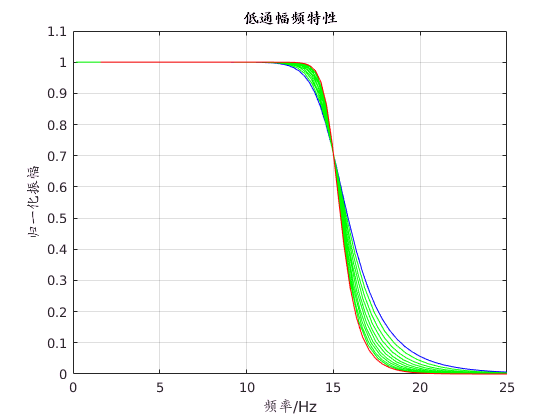

figure;
for n=staN:endN
    [z,p,k]=butter(n,wn,ftype,'s');
    [b,a]=zp2tf(z,p,k);
    [h,w]=freqs(b,a);
    
    co='g';
    if n==staN 
        co='b';     % 蓝色为低阶端
    end
    if n==endN
        co='r';     % 红色为高阶端
    end
    plot(w/(2*pi),abs(h),co);
    hold on;
end 
axis([0 25 0 1.1]);
ylabel('归一化振幅');
grid on;
xlabel('频率/Hz');   
set(gca,'YTick',0:0.1:1.1);
title('低通幅频特性')

计算巴特沃斯低通滤波器相频特性

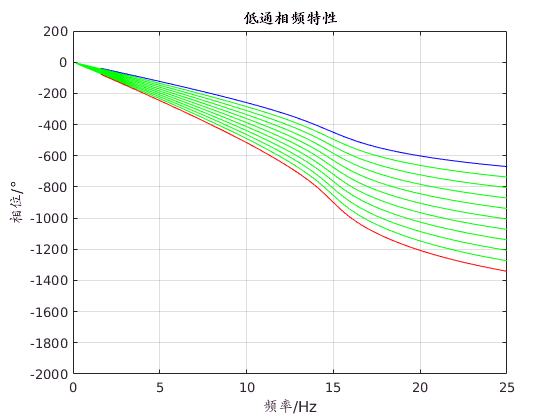

figure;
for n=staN:endN
    [z,p,k]=butter(n,wn,ftype,'s');
    [b,a]=zp2tf(z,p,k);
    [h,w]=freqs(b,a);
    
    co='g';
    if n==staN 
        co='b';     % 蓝色为低阶端
    end
    if n==endN
        co='r';     % 红色为高阶端
    end    
      plot(w/(2*pi),unwrap(angle(h))*180/pi,co);
    hold on;
end
axis([0 25 -2000 200]);
ylabel('相位/°');
grid on;
xlabel('频率/Hz');
title('低通相频特性')

## 计算巴特沃斯高通滤波器幅频特性和相频特性

staN=10;
endN=20;
fn=5;            
wn=fn*2*pi;
ftype='high';

计算巴特沃斯高通滤波器幅频特性

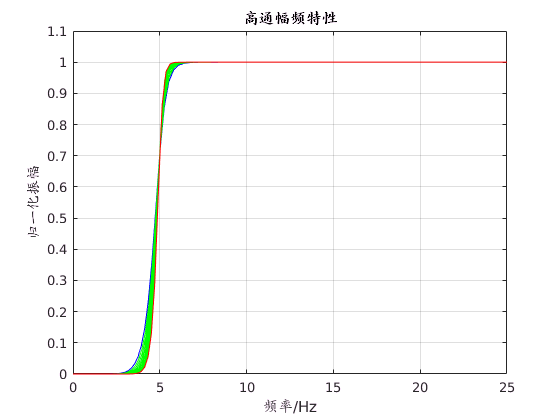

figure;
for n=staN:1:endN
    [z,p,k]=butter(n,wn,ftype,'s');
    [b,a]=zp2tf(z,p,k);
    [h,w]=freqs(b,a);
    
    co='g';
    if n==staN
        co='b';     %蓝色为低阶端
    end
    if n==endN
        co='r';     %红色为高阶端
    end
    plot(w/(2*pi),abs(h),co);
    hold on;
end 
ylabel('归一化振幅');
axis([0 25 0 1.1]);
grid on;
xlabel('频率/Hz');
set(gca,'YTick',0:0.1:1.1);
title('高通幅频特性')

计算巴特沃斯高通滤波器相频特性

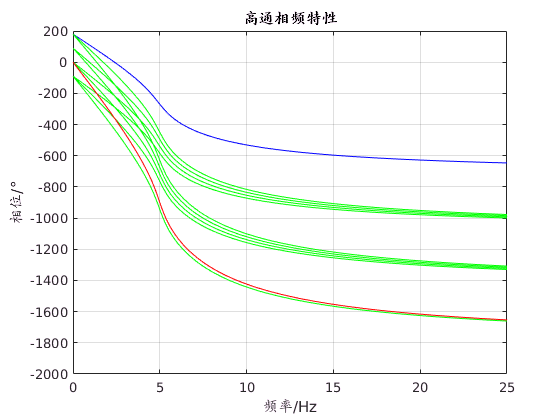

figure;
for n=staN:1:endN
    
    [z,p,k]=butter(n,wn,ftype,'s');
    [b,a]=zp2tf(z,p,k);
    [h,w]=freqs(b,a);
    
    co='g';
    if n==staN
        co='b';     %蓝色为低阶端
    end
    if n==endN
        co='r';     %红色为高阶端
    end    
    plot(w/(2*pi),unwrap(angle(h))*180/pi,co);
    hold on;
end
axis([0 25 -2000 200]);
ylabel('相位/°');
grid on
xlabel('频率/Hz')
title('高通相频特性')

## 计算巴特沃斯带通滤波器幅频特性和相频特性

staN=5;
endN=10;
fn1=5;   
fn2=15;
wn=[fn1 fn2]*2*pi;

计算巴特沃斯带通滤波器幅频特性

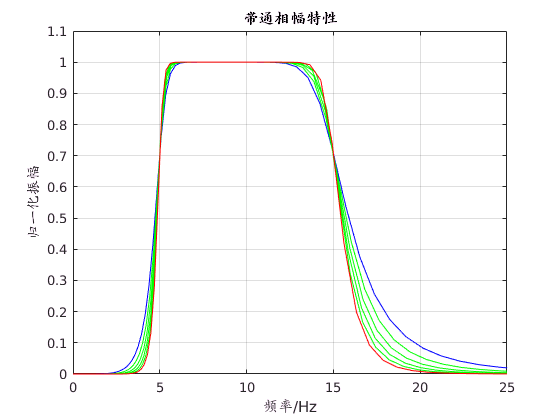

figure;
for n=staN:1:endN
    [z,p,k]=butter(n,wn,'s');
    [b,a]=zp2tf(z,p,k);
    [h,w]=freqs(b,a);
    
    co='g';
    if n==staN
        co='b';   %蓝色为低阶端
    end
    if n==endN
        co='r';    %红色为高阶端
    end
    plot(w/(2*pi),abs(h),co);
    hold on;
end
ylabel('归一化振幅');
grid on;
xlabel('频率/Hz');
axis([0 25 0 1.1]);
set(gca,'YTick',0:0.1:1.1);
title('带通相幅特性')

计算巴特沃斯带通滤波器相频特性

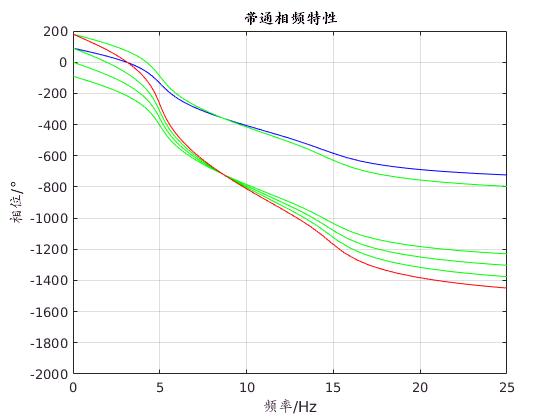

figure;
for n=staN:1:endN
    [z,p,k]=butter(n,wn,'s');
    [b,a]=zp2tf(z,p,k);
    [h,w]=freqs(b,a);
    
    co='g';
    if n==staN
        co='b';   %蓝色为低阶端
    end
    if n==endN
        co='r';    %红色为高阶端
    end    
    plot(w/(2*pi),unwrap(angle(h))*180/pi,co);
    hold on;
end
axis([0 25 -2000 200]);
ylabel('相位/°');
grid on;
xlabel('频率/Hz');
title('带通相频特性')

## 计算零极点

% 当阶数相同且截止频率相同时，高通和低通有相同的极点值。
fn=15;
n=5;
wn=fn*2*pi;

用butter函数计算，低通滤波器极点值p

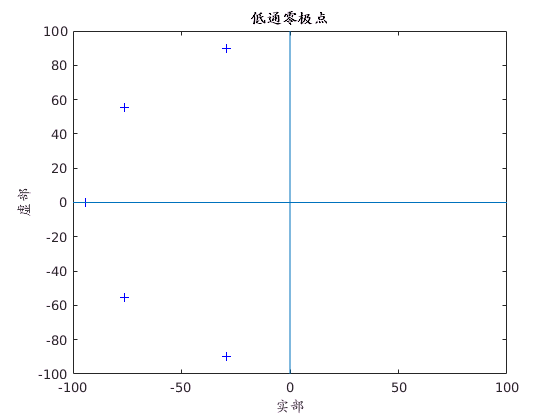

% 低通有0个零点
[lowz,lowp,k]=butter(n,wn,'low','s');
figure;
plot(real(lowp),imag(lowp),'b+');
line([-100,100],[0,0]);
line([0,0],[-100,100]);
axis([-100 100 -100 100]);
xlabel('实部');
ylabel('虚部');
title('低通零极点')

用butter函数计算，高通滤波器极点值p

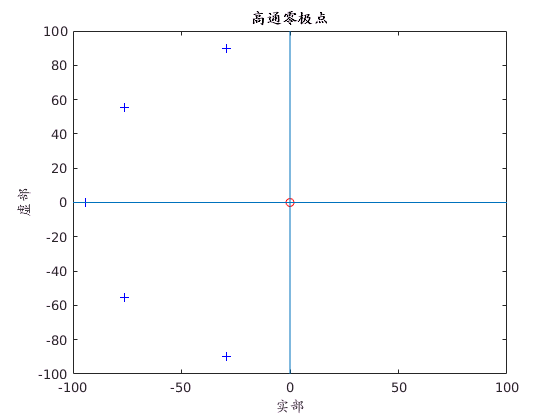

[highz,highp,k]=butter(n,wn,'high','s');
figure;
plot(real(highp),imag(highp),'b+');
hold on;
plot(real(highz),imag(highz),'ro');
line([-100,100],[0,0]);
line([0,0],[-100,100]);
axis([-100 100 -100 100]);
xlabel('实部');
ylabel('虚部');
title('高通零极点')

用butter函数计算，带通极点值p

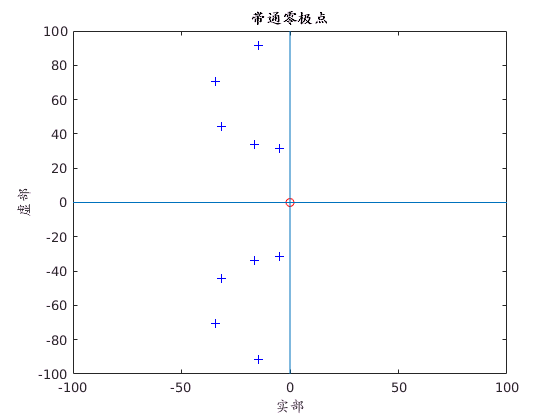

wn=[5 15]*2*pi;
[bandz,bandp,k]=butter(n,wn,'bandpass','s');
figure;
plot(real(bandp),imag(bandp),'b+');
hold on;
plot(real(bandz),imag(bandz),'ro');
line([-100,100],[0,0]);
line([0,0],[-100,100]);
axis([-100 100 -100 100]);
xlabel('实部');
ylabel('虚部');
title('带通零极点')

%???高通和低通的极点计算公式为什么一样--------------------------------------???

% fn1=15;
% wn1=fn1*2*pi;
% n=5;
% s = zeros(1,n);
% 
% % 低通滤波器
% % 按极点定义式计算极点值s
% for k=1:n
%     alpha=((2*k-1)*pi/(2*n)+pi/2);
%     s(k)=wn1*(cos(alpha)+1i*sin(alpha));
% end
% 
% % 高通滤波器
% % 按极点定义式计算极点值s
% for k=1:n
%     alpha=((2*k-1)*pi/(2*n)+pi/2);
%     s(k)=wn1*(cos(alpha)+1i*sin(alpha));
% end